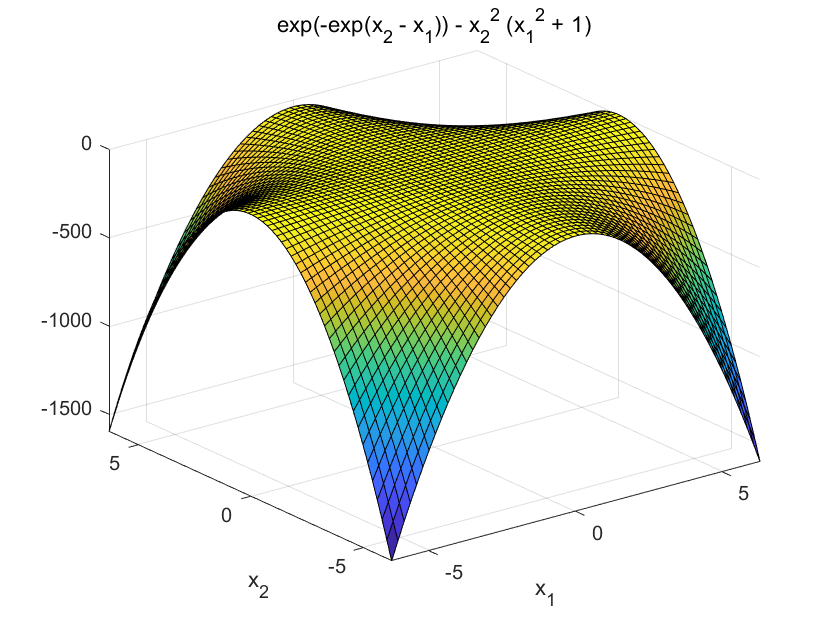

syms x1 x2
F(1) = exp(-exp(-x1+x2))-x2^2*(1+x1^2);
F(2) = x1*tan(x2)+x2*sin(x1)-0.5;
figure(1)
ezsurf(F(1))

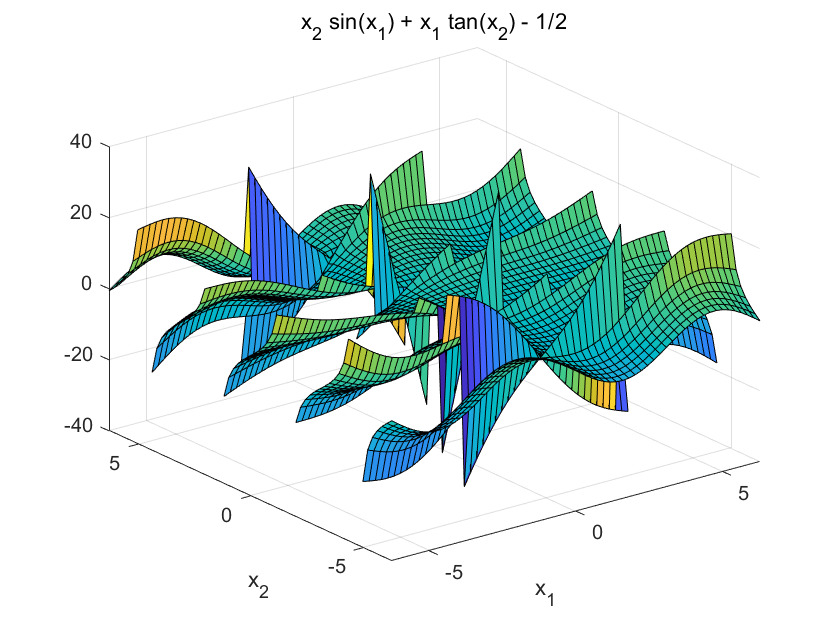

ans = 包含以下字段的 struct :
    x1: [1×1 sym]
    x2: [1×1 sym]


figure(2)
ezsurf(F(2))

x = fsolve(@func11,[1,1])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



x =     0.4547    0.5307


options = optimoptions('fsolve');
options.Algorithm = 'levenberg-marquardt'

options =   fsolve options:

   Options used by current Algorithm ('levenberg-marquardt'):
   (Other available algorithms: 'trust-region', 'trust-region-dogleg')

   Set properties:
                   Algorithm: 'levenberg-marquardt'

   Default properties:
              CheckGradients: 0
                     Display: 'final'
    FiniteDifferenceStepSize: 'sqrt(eps)'
        FiniteDifferenceType: 'forward'
           FunctionTolerance: 1.0000e-06
      MaxFunctionEvaluations: '200*numberOfVariables'
               MaxIterations: 400
                   OutputFcn: []
                     PlotFcn: []
    SpecifyObjectiveGradient: 0
               StepTolerance: 1.0000e-06
                    TypicalX: 'ones(numberOfVariables,1)'
                 UseParallel: 0

  

x = fsolve(@func11,[1,1],options)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



x =     0.4547    0.5307


syms C N sigma alpha phi
U = C^(1-sigma)/(1-sigma) - alpha*N^(1+phi)/(1+phi);

syms C0 N0
Ut = taylor(U,[C,N],[C0,N0],'order',2)

$$Ut = \frac{{\mathrm{e}}^{-\log\left(C_{0}\right)\,\left(\sigma -1\right)}\,\left(C-C_{0}\right)}{C_{0}}-\frac{\alpha \,{\mathrm{e}}^{\log\left(N_{0}\right)\,\left(\phi +1\right)}}{\phi +1}-\frac{{\mathrm{e}}^{-\log\left(C_{0}\right)\,\left(\sigma -1\right)}}{\sigma -1}-\frac{\alpha \,{\mathrm{e}}^{\log\left(N_{0}\right)\,\left(\phi +1\right)}\,\left(N-N_{0}\right)}{N_{0}}$$

syms u v
logU = subs(U,[C,N],[exp(u)*C0,exp(v)*N0])

$$logU = -\frac{{\left(C_{0}\,{\mathrm{e}}^{u}\right)}^{1-\sigma }}{\sigma -1}-\frac{\alpha \,{\left(N_{0}\,{\mathrm{e}}^{v}\right)}^{\phi +1}}{\phi +1}$$

logUt = taylor(logU,[u,v],[0,0],'order',2)

$$logUt = u\,{\mathrm{e}}^{-\log\left(C_{0}\right)\,\left(\sigma -1\right)}-\frac{{\mathrm{e}}^{-\log\left(C_{0}\right)\,\left(\sigma -1\right)}}{\sigma -1}-\frac{\alpha \,{\mathrm{e}}^{\log\left(N_{0}\right)\,\left(\phi +1\right)}}{\phi +1}-\alpha \,v\,{\mathrm{e}}^{\log\left(N_{0}\right)\,\left(\phi +1\right)}$$

syms C N sigma alpha phi
U = (C-alpha*N^(1+phi)/(1+phi))^(1-sigma)/(1-sigma)

$$U = -\frac{{\left(C-\frac{N^{\phi +1}\,\alpha }{\phi +1}\right)}^{1-\sigma }}{\sigma -1}$$

syms C0 N0
Ut = taylor(U,[C,N],[C0,N0],'order',2)

$$Ut = \begin{array}{l} \frac{\sigma_{1}\,\left(C-C_{0}\right)}{C_{0}-\frac{\alpha \,{\mathrm{e}}^{\log\left(N_{0}\right)\,\left(\phi +1\right)}}{\phi +1}}-\frac{\sigma_{1}}{\sigma -1}-\frac{\alpha \,{\mathrm{e}}^{\log\left(N_{0}\right)\,\left(\phi +1\right)}\,\sigma_{1}\,\left(N-N_{0}\right)}{N_{0}\,\left(C_{0}-\frac{\alpha \,{\mathrm{e}}^{\log\left(N_{0}\right)\,\left(\phi +1\right)}}{\phi +1}\right)}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\log\left(C_{0}-\frac{\alpha \,{\mathrm{e}}^{\log\left(N_{0}\right)\,\left(\phi +1\right)}}{\phi +1}\right)\,\left(\sigma -1\right)} \end{array}$$

syms u v
logU = subs(U,[C,N],[exp(u)*C0,exp(v)*N0]);
logUt = taylor(logU,[u,v],[0,0],'order',2)

$$logUt = \begin{array}{l} \frac{C_{0}\,u\,\sigma_{1}}{C_{0}-\frac{\alpha \,{\mathrm{e}}^{\log\left(N_{0}\right)\,\left(\phi +1\right)}}{\phi +1}}-\frac{\sigma_{1}}{\sigma -1}-\frac{\alpha \,v\,{\mathrm{e}}^{\log\left(N_{0}\right)\,\left(\phi +1\right)}\,\sigma_{1}}{C_{0}-\frac{\alpha \,{\mathrm{e}}^{\log\left(N_{0}\right)\,\left(\phi +1\right)}}{\phi +1}}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\log\left(C_{0}-\frac{\alpha \,{\mathrm{e}}^{\log\left(N_{0}\right)\,\left(\phi +1\right)}}{\phi +1}\right)\,\left(\sigma -1\right)} \end{array}$$